# Problem 13-55

clear
constants

G =      6.67e-11

Earth


Me =      5.98e+24

Re =      6370000

Sun


Ms =      1.99e+30

Jupiter


Mj =     1.898e+27

Galileo's observation

name = ['Io' 'Europa' 'Ganymede' 'Calisto']

name = 'IoEuropaGanymedeCalisto'

a = [4.22 6.71 10.7 18.8]*1e8   % m

a =      4.22e+08     6.71e+08     1.07e+09     1.88e+09


T = [1.77 3.55 7.16 16.7]       % days

T =          1.77         3.55         7.16         16.7


(a) plot log a (y-axis) against log T (x-axis)

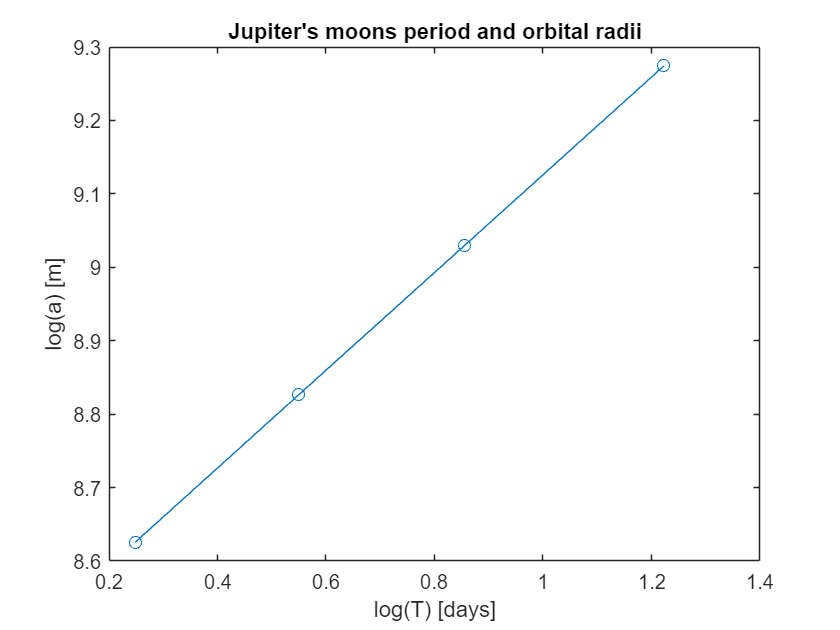

Tlog = log10(T);
alog = log10(a);
plot(Tlog,alog, 'o-')
xlabel('log(T) [days]'), ylabel('log(a) [m]')
title("Jupiter's moons period and orbital radii")

(b) Slope of the line

da = alog(4)-alog(1);
dT = Tlog(4)-Tlog(1);
slope = da/dT

slope =       0.66566

(c) Mass of Jupiter from the intercept of this line with the y axis at log(T) = 0 where T = 1 and use $T^2 = \frac{4\pi^2}{GM} a^3$. Thus $2\log T = \log\left(\frac{4\pi^2}{GM}\right) + 3\log a$ and $\log T = 0$ leading $\log\frac{4\pi^2}{GM} = -3 \log a$ and $\frac{4\pi^2}{GM} = 10^{-3 \log a}$ finally $M = \frac{4\pi^2}{G \cdot 10^{-3\log a}$

ai = interp1(log10(T*24*3600),log10(a),0,"linear","extrap") % intercept at log(T) = 0 on y axis by extrapolation

ai =        5.1706

M = 4*pi^2/(G*10^(-3*ai));
disp(['mass of Jupiter: ' num2str(M,3) ' kg'])

mass of Jupiter: 1.92e+27 kg
